load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29


sum(sum(ismissing(HCV)))

ans = 0

HCV1=HCV;

for j=1:1385
    
    %Age
    if HCV.Age(j)<32
    HCV1.Age(j)=1;
    else
        if HCV.Age(j)<37
            HCV1.Age(j)=2;
        else 
            if HCV.Age(j)<42
                HCV1.Age(j)=3;
            else
                if HCV.Age(j)<47
                    HCV1.Age(j)=4;
                else
                    if HCV.Age(j)<52
                        HCV1.Age(j)=5;
                    else 
                        if HCV.Age(j)<57
                            HCV1.Age(j)=6;
                        else 
                            if HCV.Age(j)<62
                                HCV1.Age(j)=7;
                            end
                        end
                    end
                end
            end
        end
    end
    
    %BMI
    if HCV1.BMI(j)<18.5
        HCV1.BMI(j)=1;
    else
        if HCV1.BMI(j)<25
            HCV1.BMI(j)=2;
        else
            if HCV1.BMI(j)<30
                HCV1.BMI(j)=3;
            else
                if HCV1.BMI(j)<35
                    HCV1.BMI(j)=4;
                else
                    if HCV1.BMI(j)<40
                        HCV1.BMI(j)=5;
                    end 
                end
            end
        end 
    end
    
    % WBC
    if HCV.WBC(j)<4000
        HCV1.WBC(j)=1;
    else
        if HCV.WBC(j)<11000
            HCV1.WBC(j)=2;
        else
            HCV1.WBC(j)=3;
        end
    end
    
    %RBC
    if HCV.RBC(j)<3000000
        HCV1.RBC(j)=1;
    else
        if HCV.RBC(j)<5000000
            HCV1.RBC(j)=2;
        else
            HCV1.RBC(j)=3;
        end
    end
    
    %Platelet
    if HCV.Plat(j)<100000
        HCV1.Plat(j)=1;
    else 
        if HCV.RBC(j)<255000
            HCV1.Plat(j)=2;
        else
            HCV1.Plat(j)=3;
        end
    end
   
   %HGB
   if HCV.Gender(j)==1
    if HCV.HGB(j)<14
        HCV1.HGB(j)=1;
    else
        if HCV.HGB(j)<17.5
            HCV1.HGB(j)=2;
        else
            HCV1.HGB(j)=3;
        end
    end
   else
    if HCV.HGB(j)<12.3
        HCV1.HGB(j)=4;
    else
        if HCV.HGB(j)<15.3
            HCV1.HGB(j)=5;
        else
            HCV1.HGB(j)=6;
        end
    end
   end
   
   %AST, ALTs
   for i=15:23
    if HCV.(i)(j)<20
        HCV1.(i)(j)=1;
    else
        if HCV.(i)(j)<40
            HCV1.(i)(j)=2;
        else
            HCV1.(i)(j)=3;
        end
    end
   end
   
   %RNAs
   for i=24:27
    if HCV.(i)(j)<=5
        HCV1.(i)(j)=1;
    else
        HCV1.(i)(j)=2;
    end
   end
   
end
Stage=HCV1.(29);
Stage(Stage<3)=0;
Stage(Stage>2)=1;
HCV.(29)=Stage;

## Entire Dataset is categorical now

HCV1

HCV1 = 1385×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain    WBC    RBC    HGB    Plat    AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w    RNABase    RNA4    RNA12    RNAEOT    RNAEF    BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    _____________   

HCV1_array=table2array(HCV1)

HCV1_array =      6     1     5     2     1     1     1     2     2     2     2     2     2     3     3     3     3     3     3     1     1     1     3     2     2     1     1    13     2
     4     1     3     1     2     2     1     2     2     1     3     2     1     3     3     3     3     3     3     3     3     3     3     2     2     2     2     4     2
     7     1     4     2     2     2     2     1     1     1     2     2     1     3     3     3     3     3     3     1     1     1     3     2     1     2     2     4     4
     5     2     4     1     2     1     2     1     2     1     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2    10     3
     7     1     4     1     1     2     1     2     2     2     1     2     1     3     3     3     3     3     3     3     3     2     3     2     2     2     2    11     1
     7     2     2     2     2     2     1     2     2     1     3     2     5     3     3     3     3     3    

% There is no point removing outliers here.
% PCA cannot be used for categorical 

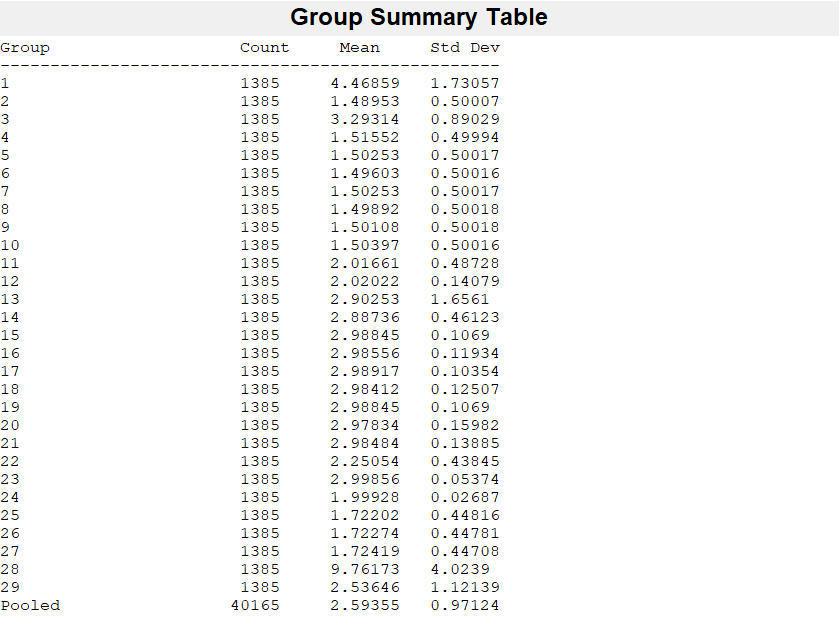

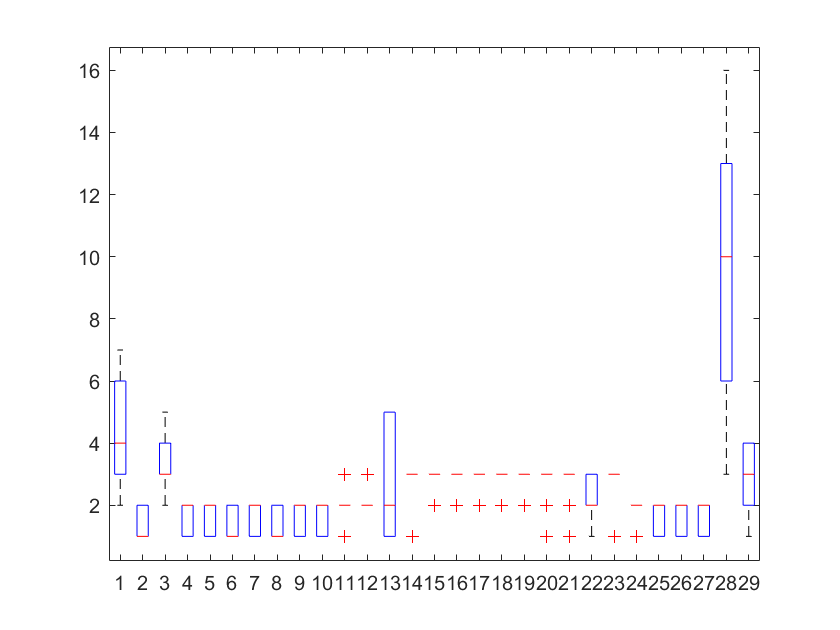

p = 0

stats = struct with fields:
    chisqstat: 8.3668e+04
           df: 28


[p,stats] = vartestn(HCV1_array)

for i=1:29
    [h(i),p(i)]=chi2gof(HCV1_array(:,i));
end

[p',h']%gives NaN values

ans =     0.0000    1.0000
         0    1.0000
         0    1.0000
         0    1.0000
         0    1.0000
         0    1.0000
         0    1.0000
         0    1.0000
         0    1.0000
         0    1.0000


### Unsupervised feature selection

K-mediods clustering

%K-mediods clustering for categorical variables
Xz=double(categorical(HCV1_array(:,1:27)))

Xz =      6     1     5     2     1     1     1     2     2     2     2     2     2     3     3     3     3     3     3     1     1     1     3     2     2     1     1
     4     1     3     1     2     2     1     2     2     1     3     2     1     3     3     3     3     3     3     3     3     3     3     2     2     2     2
     7     1     4     2     2     2     2     1     1     1     2     2     1     3     3     3     3     3     3     1     1     1     3     2     1     2     2
     5     2     4     1     2     1     2     1     2     1     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     7     1     4     1     1     2     1     2     2     2     1     2     1     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     7     2     2     2     2     2     1     2     2     1     3     2     5     3     3     3     3     3     3     3     3     2     3     2     1     1     1
     4     2     

k_values=2:10;
n=length(k_values);
s_score=zeros(n,1);
for i=1:n
    idxk=kmedoids(Xz,k_values(i),'Distance',"hamming");
    s=silhouette(Xz,idxk);
    s_score(i)=mean(s);
end
table(k_values',s_score)

ans = 9×2 table
    Var1     s_score  
    ____    __________

      2         0.1207
      3        0.08173
      4       0.021881
      5      -0.009058
      6      0.0032559
      7      -0.021438
      8     -0.0018265
      9      -0.032429
     10      -0.022163


k=find(s_score==max(s_score))+1

k = 2


idxk=kmedoids(Xz,k,"Distance","hamming")

idxk =      1
     1
     1
     1
     1
     1
     2
     1
     1
     1


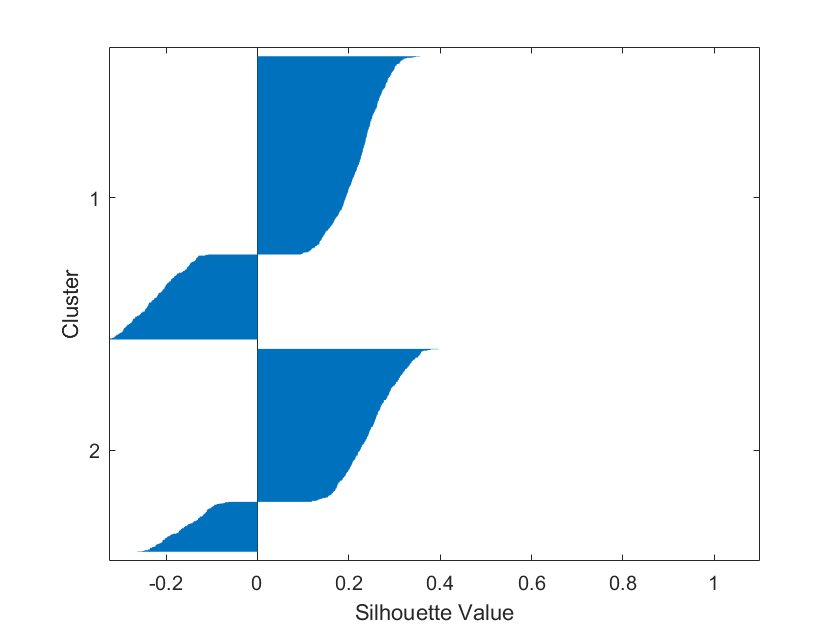

silhouette(Xz,idxk)

Laplacian Scores

% Ranks features (variables) in X using the Laplacian scores. 
% The function returns idx, which contains the indices of features ordered by 
% feature importance. 
% You can use idx to select important features for unsupervised learning.
[idxl, scores]=fsulaplacian(HCV1_array(:,1:27))

idxl =      2    23    14    26    27    25    13     1    24     3    21    15    16    20     5     4     7     6     9    10     8    17    11    22    19    12    18


scores =     0.9774    1.0000    0.9126    0.8309    0.8318    0.8251    0.8274    0.8205    0.8249    0.8220    0.8174    0.7972    0.9857    0.9915    0.8637    0.8416    0.8191    0.7641    0.8082    0.8381    0.8755    0.8139    0.9968    0.9317    0.9909    0.9911    0.9909



D = pdist(HCV1_array(:,1:27));
Z = squareform(D);
S = exp(-Z.^2);
issymmetric(S);
idx = fsulaplacian(HCV1_array(:,1:27),'Similarity',S)

idx =      2    23    14    13     1    26    27    25    24     3    21    15    16    20    11    17    19     5     4     7    10     6     9     8    12    22    18


x=HCV1_array(:,1:27);
y=HCV1_array(:,29);
[Xtrain, Ytrain, Xtest, Ytest]=trainTestSplit(x,y,0.7);
xn=normalize(HCV1_array(:,1:27),'range');
yn=HCV1_array(:,29);
[Xtrainn, Ytrainn, Xtestn, Ytestn]=trainTestSplit(xn,yn,0.7);

# Multinomial Logistic regression

%Without Normalization
[b1,dev1,stats1]=mnrfit(Xtrain,categorical(Ytrain))

Error using linsolve
Matrix must be positive definite.

Error in mnrfit (line 252)
            bcov = linsolve(hess,eye(size(hess)),struct('SYM',true,'POSDEF',true));

[val,pred1]=max(mnrval(b1,Xtest)')
pred1=normalize(pred1','range')
accuracy1=sum(pred1==Ytest)/length(Ytest)
confusionmat(double(Ytest),double(pred1))

%With normalization
[b1n,dev1n,stats1n]=mnrfit(Xtrainn,Ytrainn)
[valn,pred1n]=max(mnrval(b1n,Xtestn)')
pred1n=normalize(pred1n','range')
accuracy1n=sum(pred1n==Ytestn)/length(Ytestn)
confusionmat(double(Ytestn),double(pred1n))

X=HCV1_array(:,1:27);
Y=categorical(HCV1.Baselinehistologicalstaging);
class(X)

ans = 'double'

class(Y)

ans = 'categorical'

[B,dev,stats] = mnrfit(X,Y,'model','hierarchical');

stats.p

ans =     0.9986       NaN       NaN
    0.4976    0.2472    0.1859
    0.3245    0.6215    0.2708
    0.6374    0.0014    0.2523
    0.3566    0.5250    0.2306
    0.0989    0.2040    0.9549
    0.8047    0.8212    0.8804
    0.3426    0.5420    0.8822
    0.3957    0.4313    0.3757
    0.1802    0.2113    0.4578


Column 1 : Stage 1 Vs >1   Column 2 : Stage 2 Vs >2 (Moderate Vs Adv.)     Column 3 : Stage 3 Vs >3

Row 1 : Intercept

Significant variables for Stage 1 vs greater : 5,10  remove  6,11,22:27 threshold 0.8

Significant variable for Mod. Vs Adv. : 20, 3   remove 6,12,14, 23:27

Significant variable for Stage 3 vs greater : 20, 3   remove 5:7,17, 22:27

%remove 23:27
X=HCV1_array(:,1:22);
Y=categorical(HCV1.Baselinehistologicalstaging);
class(X)

ans = 'double'

class(Y)

ans = 'categorical'

[B,dev,stats] = mnrfit(X,Y,'model','hierarchical');
stats.p

ans =     0.1395    0.3922    0.0847
    0.4613    0.2165    0.1878
    0.2906    0.6262    0.2459
    0.6381    0.0012    0.2531
    0.3927    0.5679    0.2516
    0.1057    0.1941    0.9983
    0.7640    0.8662    0.9040
    0.3858    0.5230    0.8313
    0.3491    0.4588    0.3492
    0.2016    0.2226    0.4691
